a = [1 2 3];
a

a =      1     2     3


b = a.';
b

b =      1
     2
     3


c = a * b;
c

c = 14

c = a.*a;
c

c =      1     4     9


t = linspace(0,2*pi,10000);
y1 = 0;
for i = 1:10000
    f1 = sin(5*t(i)).^2;
    y1 = y1 + f1*pi/5000;
end
y1

y1 = 3.1413

t = linspace(0,1,10000);
y2 = 0;
for i = 1:10000
    f2 = exp(t(i));
    y2 = y2 + f2/10000;
end
y2

y2 = 1.7183

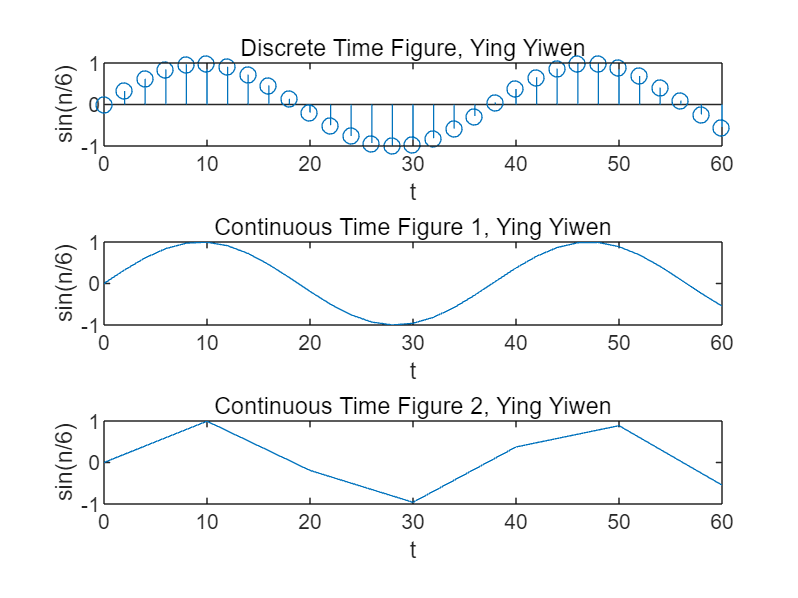

figure;
n = 0:2:60;
y = sin(n/6);
subplot(3,1,1),stem(n,y),title('Discrete Time Figure, Ying Yiwen'),xlabel('t'),ylabel('sin(n/6)');
n1 = 0:2:60;
z = sin(n1/6);
subplot(3,1,2),plot(n1,z),title('Continuous Time Figure 1, Ying Yiwen'),xlabel('t'),ylabel('sin(n/6)');
n2 = 0:10:60;
w = sin(n2/6);
subplot(3,1,3),plot(n2,w),title('Continuous Time Figure 2, Ying Yiwen'),xlabel('t'),ylabel('sin(n/6)');

Continuous Time Figure 1, with step size 2, almost show the shape of the function, while Continuous Time Figure 2, with step size 10, can't clearly refelect the shape of the function.

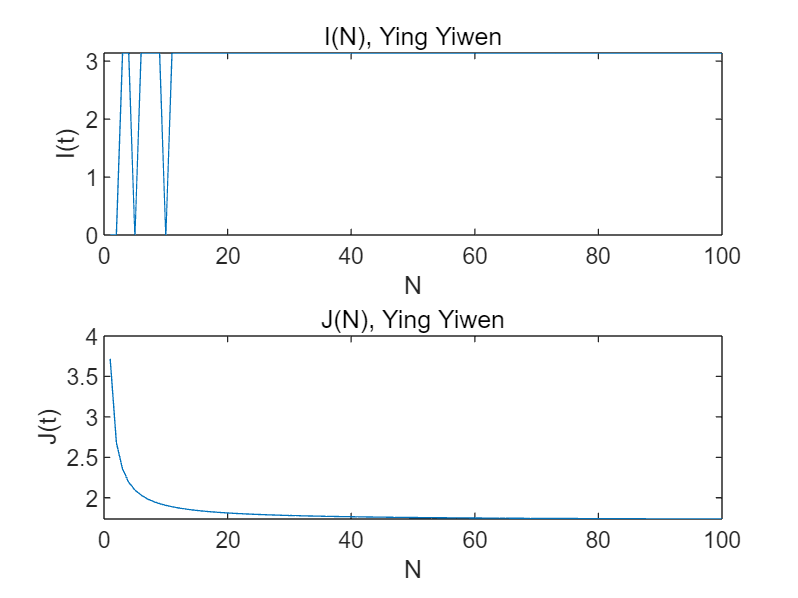

N=1:1:100;
I = [];
J = [];
for i = 1:100
    I = [I integ1(N(i))];
    J = [J integ2(N(i))];
end
figure;
subplot(2,1,1),plot(N,I),title('I(N), Ying Yiwen'),xlabel('N'),ylabel('I(t)');
subplot(2,1,2),plot(N,J),title('J(N), Ying Yiwen'),xlabel('N'),ylabel('J(t)');

For I(5) and I(10), each sample point meets sin(5*t)^2=0, so the sum of the function is also zero.

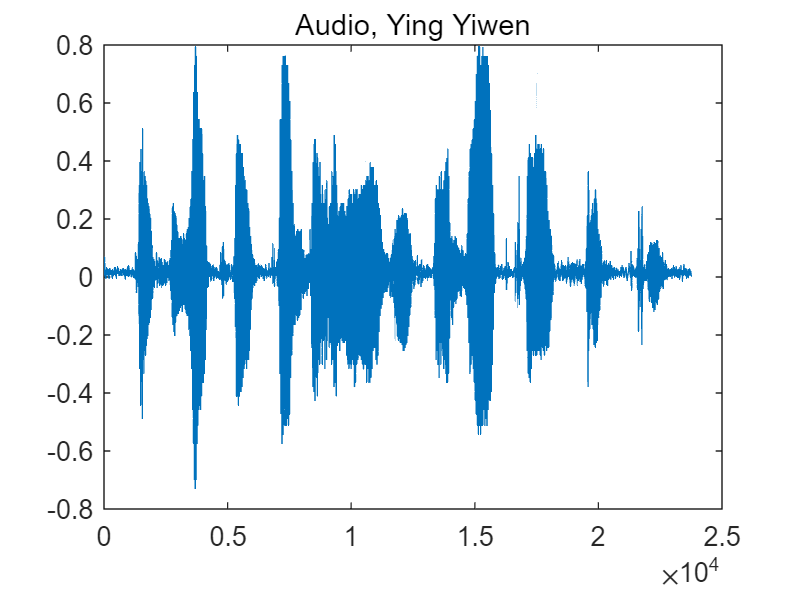

audio = audioread("speech.au");
figure;
plot(audio),title('Audio, Ying Yiwen');

sound(audio);

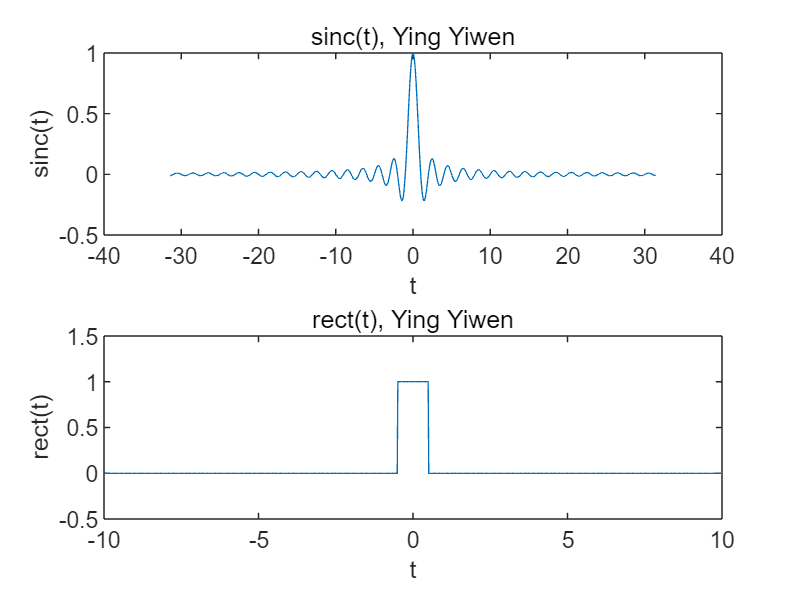

figure;
t = linspace(-10*pi, 10*pi, 1000);
f = sinc(t);
subplot(2,1,1),plot(t,f),title('sinc(t), Ying Yiwen'),xlabel('t'),ylabel('sinc(t)');
t = linspace(-10, 10, 1000);
f = (abs(t)<=0.5);
subplot(2,1,2),plot(t,f),title('rect(t), Ying Yiwen'),xlabel('t'),ylabel('rect(t)'),ylim([-0.5, 1.5]);

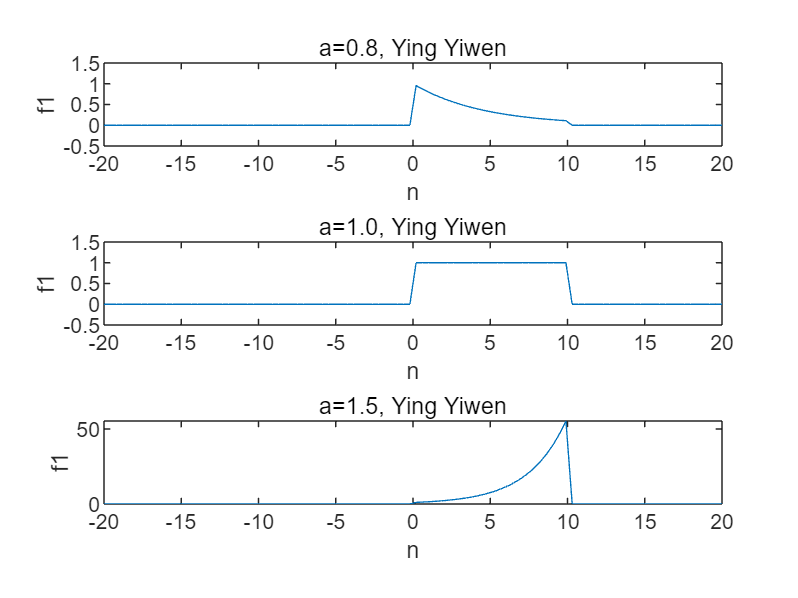

figure;
orient("tall");
subplot(3,1,1),draw1(0.8),title('a=0.8, Ying Yiwen'),xlabel('n'),ylabel('f1'),ylim([-0.5, 1.5]);
subplot(3,1,2),draw1(1),title('a=1.0, Ying Yiwen'),xlabel('n'),ylabel('f1'),ylim([-0.5, 1.5]);
subplot(3,1,3),draw1(1.5),title('a=1.5, Ying Yiwen'),xlabel('n'),ylabel('f1');

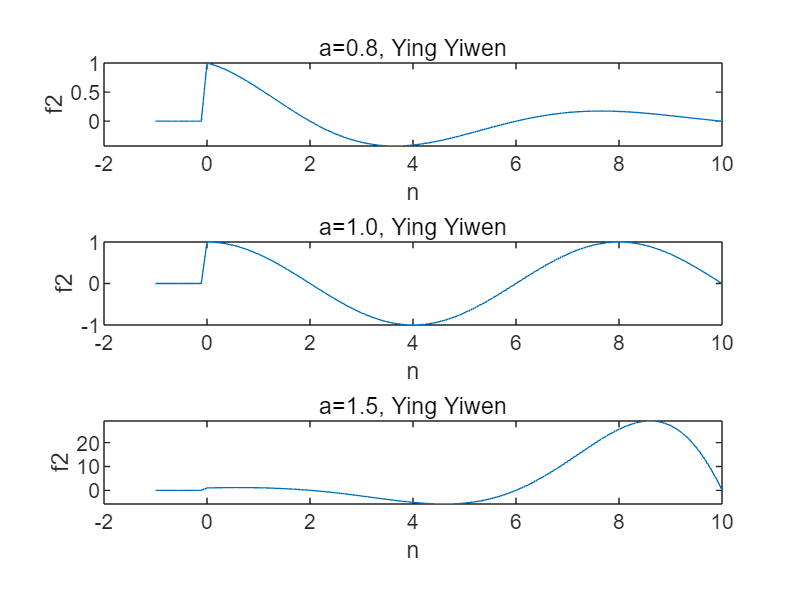

figure;
orient("tall");
subplot(3,1,1),draw2(0.8),title('a=0.8, Ying Yiwen'),xlabel('n'),ylabel('f2');
subplot(3,1,2),draw2(1),title('a=1.0, Ying Yiwen'),xlabel('n'),ylabel('f2');
subplot(3,1,3),draw2(1.5),title('a=1.5, Ying Yiwen'),xlabel('n'),ylabel('f2');

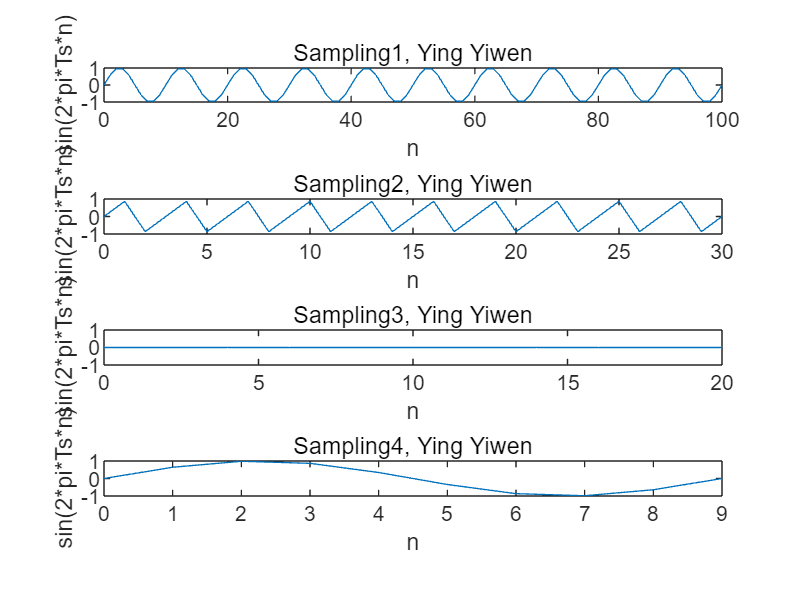

figure;
orient("tall");
subplot(4,1,1),draw3(1/10,100),axis([0,100,-1,1]),title('Sampling1, Ying Yiwen');
subplot(4,1,2),draw3(1/3,30),axis([0,30,-1,1]),title('Sampling2, Ying Yiwen');
subplot(4,1,3),draw3(1/2,20),axis([0,20,-1,1]),title('Sampling3, Ying Yiwen');
subplot(4,1,4),draw3(10/9,9),axis([0,9,-1,1]),title('Sampling4, Ying Yiwen');

According to the four figures above, the sampled version of Ts=1/10 best reflects the shape of the function.

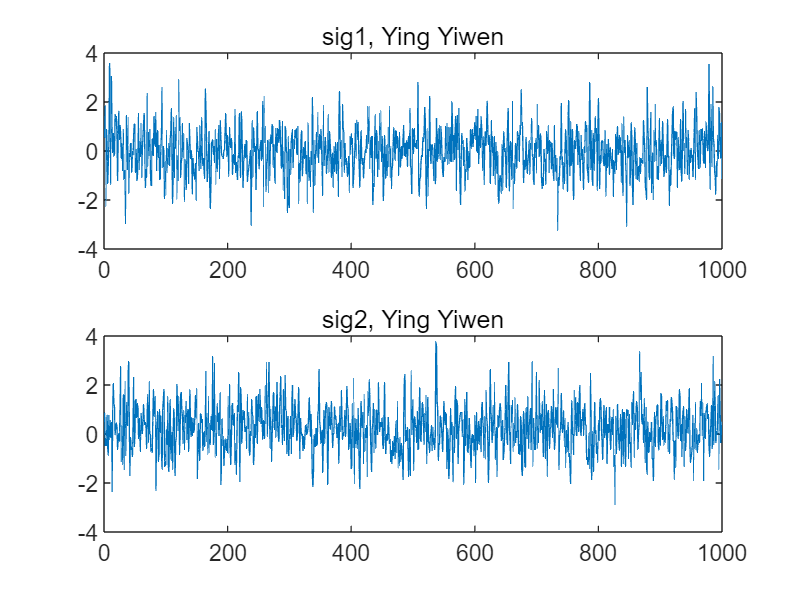

figure;
sig1 = random('norm',0,sqrt(1),1,1000);
subplot(2,1,1),plot(sig1),title('sig1, Ying Yiwen');
sig2 = random('norm',0.2,sqrt(1),1,1000);
subplot(2,1,2),plot(sig2),title('sig2, Ying Yiwen');

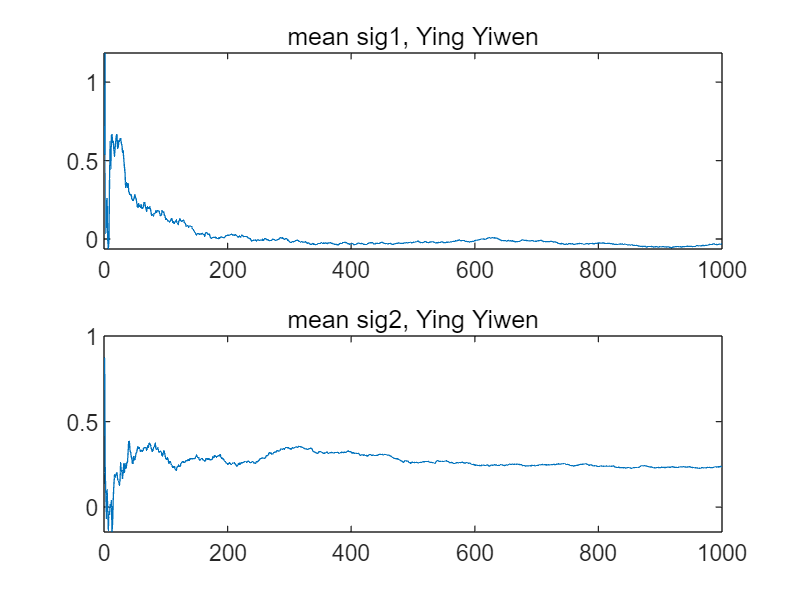

n = 1:1:1000;
ave1 = arrayfun(@(k) mean(sig1(1:k)), n);
ave2 = arrayfun(@(k) mean(sig2(1:k)), n);
figure;
subplot(2,1,1),plot(n,ave1),title('mean sig1, Ying Yiwen');
subplot(2,1,2),plot(n,ave2),title('mean sig2, Ying Yiwen');

When n becomes bigger, the average value of the signal can differ noises with different means. ave1 tends to be 0 while ave2 tends to be 0.2 when n becomes larger.

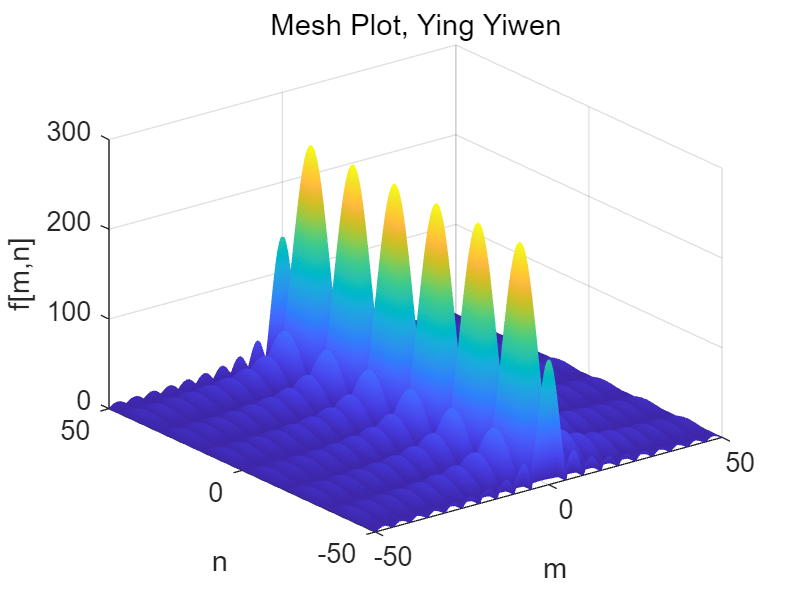

m = -50:0.1:50;
n = -50:0.1:50;
[M,N] = meshgrid(m,n);
f = 255*abs(sinc(0.2*M).*sin(0.2*N));
figure;
mesh(M,N,f),title('Mesh Plot, Ying Yiwen'),xlabel('m'),ylabel('n'),zlabel('f[m,n]');

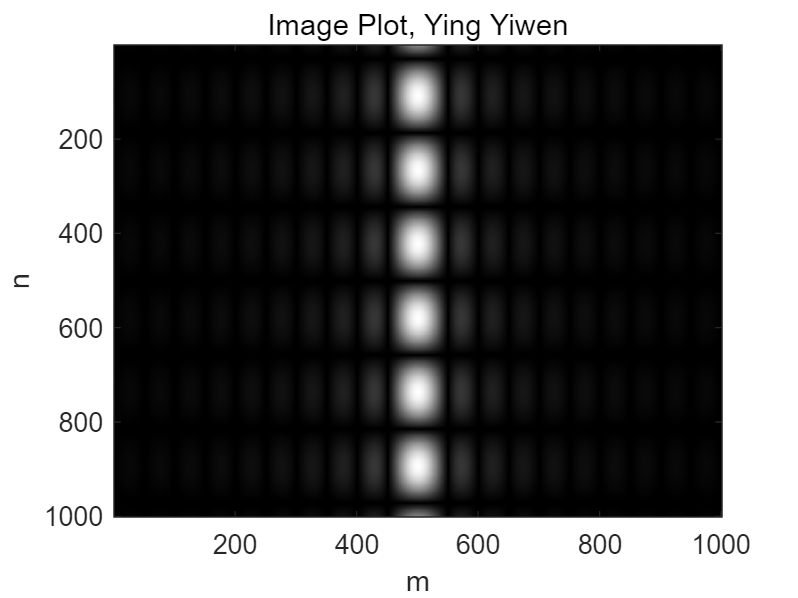

figure;
image(f),title('Image Plot, Ying Yiwen'),xlabel('m'),ylabel('n'); 
colormap(gray(256)); 

The surfcace plot can see the trend of change of the whole picture.

The image version can clearly sean the relation between different points on m and n axis.

function y = integ1(N)
    t = linspace(0,2*pi,N+1);
    f = sin(5*t).^2*2*pi/N;
    y = sum(f);
end

function y = integ2(N)
    t = linspace(0,1,N+1);
    f = exp(t)/N;
    y = sum(f);
end

function y = draw1(a)
    n = linspace(-20,20,100);
    f = a.^n .* ((n>=0)-(n>=10));
    plot(n,f);
end

function y = draw2(a)
    n = linspace(-1,10,100);
    f = cos(pi/4*n) .* a.^n .* (n>=0);
    plot(n,f);
end

function y = draw3(Ts,nmax)
    n = 0:1:nmax;
    f = sin(2*pi*Ts*n);
    plot(n,f),xlabel('n'),ylabel('sin(2*pi*Ts*n)');
end